clc
clear all;
m=load('loaddata.m');
l=load('linedata.m');
br=length(l);
numberofBuses=length(m);
[voltagesmag,active,reactive,res,ind]=indLoadFlow(m,l);
[penetrationBus, vsi]= findTargetBus(voltagesmag,active,reactive,res,ind)

penetrationBus = 72

vsi =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
         0
    0.0000
    0.0000
    0.0000


[loss,size,volt]=variation(penetrationBus,m,l)

steps =      0    50   100   150   200   250   300   350   400   450   500   550   600   650   700   750   800


loss = 	1.0e+03 *

    0.2725
    0.2678
    0.2598
    0.2509
    0.2447
    0.2453
    0.2569
    0.2839
    0.3300
    0.3986


size =      0    50   100   150   200   250   300   350   400   450   500   550   600   650   700   750   800


volt =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.9943    0.9944    0.9945    0.9947    0.9949    0.9952    0.9955    0.9959    0.9963    0.9968    0.9972    0.9977    0.9982    0.9988    0.9993    0.9999    1.0004
    0.9865    0.9867    0.9870    0.9874    0.9880    0.9887    0.9895    0.9904    0.9914    0.9924    0.9936    0.9948    0.9960    0.9972    0.9985    0.9998    1.0012
    0.9830    0.9831    0.9835    0.9841    0.9848    0.9857    0.9867    0.9879    0.9891    0.9905    0.9919    0.9934    0.9950    0.9966    0.9982    0.9999    1.0016
    0.9826    0.9828    0.9832    0.9837    0.9845    0.9853    0.9864    0.9875    0.9888    0.9901    0.9916    0.9931    0.9946    0.9962    0.9979    0.9995    1.0012
    0.9824    0.9826    0.9829    0.9835    0.9842    0.9851    0.9861    0.9873    0.9885    0.9899    0.9913    0.9928    0.9944    0.99

[minValue,idx]=min(loss)

minValue = 244.6822

idx = 5

bus=1:1:72;


% % to plot the VSI of each bus
bar(bus,vsi)
xlim([0 72])
xlabel('Bus')
ylabel('Voltage Stability Index')
xticks(bus);
xlim([0 73])
%to plot the voltage profile at each penetration of D -STATCOM
voltbase=volt(:,1)   
voltaData=volt(:,idx);
plot(bus,voltaData)
xlim([0 73])
xticks(bus);
xlabel('Buses')
ylabel('Voltage Profile in pu')
hold on
plot(bus,voltbase)

%% This code find the minimum loss point and marks the point in the graph and plot it
[min_loss, min_index] = min(loss);
ylab=0:200:1600

ylab =            0         200         400         600         800        1000        1200        1400        1600


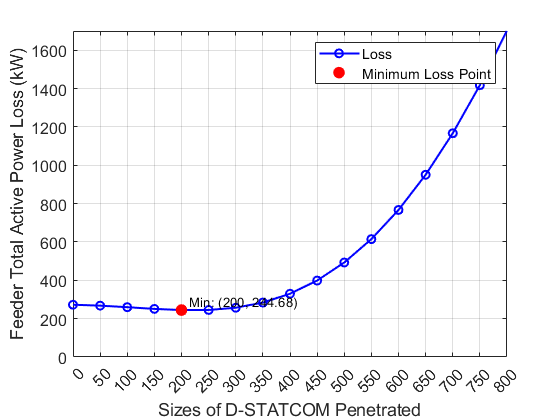

%Create the plot
figure;
plot(size, loss, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 6);
xticks(size)
yticks(ylab)
ylim([0 1700])
hold on;
plot(size(min_index), min_loss, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
xlabel('Sizes of D-STATCOM Penetrated');
ylabel('Feeder Total Active Power Loss (kW)');
legend('Loss', 'Minimum Loss Point', 'Location', 'northeast');
grid on;
text(size(min_index), min_loss, sprintf('  Min: (%.0f, %.2f)', size(min_index), min_loss), ...
     'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
set(gca, 'FontSize', 12);

set(gcf, 'Color', 'white');

function [penBus,vsi] = findTargetBus(voltagesmag,active,reactive,res,ind)
% % This bit of code calculates the voltage stability index for each bus
p=active;
q=reactive;
voltage=abs(voltagesmag);
vsi1=[];
for ho = 1: 71
    zeq= abs(res(ho)+1i*ind(ho));
    vsi1(1,end+1)= (4*(zeq)^2*q(ho+1))/(voltage(ho))^2*ind(ho);
end
[~,indices]=sort(vsi1);
penBus=indices(end)+1;
vsi1=[0,vsi1];
vsi=vsi1';
end
% this determines the minimum size of D- statcom without considering the
% Ploss
function bestSize= profile(volt)
for i=1:33
    volt1=volt(:,i);
    for k= 1:length(volt1)
        if volt1(k)<0.95 
            logic=0;
            break
        else
            logic=1;
        end
    end
    if logic==1
        bestSize=i
        break;
    end
end
end

% D_statcom Placement
function [loss,size,volt]= variation(penetrationBus,m,l)
steps=0:50:800
loss=[];
voltage1=[];
for i =1:length(steps)
    data=m(penetrationBus,3)-steps(i);
    m(penetrationBus,3)= data;
    [voltage,~,~,~,~,losses]=indLoadFlow(m,l);
    voltage1=[voltage1,voltage];
    loss=[loss,sum(losses)];
    end
loss=loss';
size=steps;
volt=voltage1;
% size=optSize;
end
% Basic load flow Function
function [voltageModify,powBranch1,qowBranch1,res,ind,losses] = indLoadFlow(m,l)
format short;
br=length(l);
no=length(m);
f=0;
d=0;
MVAb=100;
KVb=11;
Zb=(KVb^2)/MVAb;
Pg = zeros(no,1);
Pg1 = zeros(no,1);

for i=1:br
    R(i,1)=(l(i,4))/Zb;
    X(i,1)=(l(i,5))/Zb;
end
for i=1:no
    P(i,1)=(m(i,2)/(1000*MVAb));
    Q(i,1)=(m(i,3)/(1000*MVAb));
end
R;
X;
res=R;
ind=X;
powBranch1=P;
qowBranch1=Q;
C=zeros(br,no);
for i=1:br
    a=l(i,2);
    b=l(i,3);
    for j=1:no
        if a==j
            C(i,j)=-1;
        end
        if b==j
            C(i,j)=1;
        end
    end
end
C;
e=1;
for i=1:no
    d=0;
    for j=1:br
        if C(j,i)==-1
            d=1;
        end
    end
    if d==0
        endnode(e,1)=i;
        e=e+1;
    end
end
endnode;
h=length(endnode);
for j=1:h
    e=2;

    f=endnode(j,1);
    % while (f~=1)
    for s=1:no
        if (f~=1)
            k=1;
            for i=1:br
                if ((C(i,f)==1)&&(k==1))
                    f=i;
                    k=2;
                end
            end
            k=1;
            for i=1:no
                if ((C(f,i)==-1)&&(k==1));
                    f=i;
                    g(j,e)=i;
                    e=e+1;
                    k=3;
                end
            end
        end
    end
end
for i=1:h
    g(i,1)=endnode(i,1);
end
g;
w=length(g(1,:));
for i=1:h
    j=1;
    for k=1:no
        for t=1:w
            if g(i,t)==k
                g(i,t)=g(i,j);
                g(i,j)=k;
                j=j+1;
            end
        end
    end
end
g;
for k=1:br
    e=1;
    for i=1:h
        for j=1:w-1
            if (g(i,j)==k)
                if g(i,j+1)~=0
                    adjb(k,e)=g(i,j+1);
                    e=e+1;
                else
                    adjb(k,1)=0;
                end
            end
        end
    end
end
adjb;
for i=1:br-1
    for j=h:-1:1
        for k=j:-1:2
            if adjb(i,j)==adjb(i,k-1)
                adjb(i,j)=0;
            end
        end
    end
end
adjb;
x=length(adjb(:,1));
ab=length(adjb(1,:));
for i=1:x
    for j=1:ab
        if adjb(i,j)==0 && j~=ab
            if adjb(i,j+1)~=0
                adjb(i,j)=adjb(i,j+1);
                adjb(i,j+1)=0;
            end
        end
        if adjb(i,j)~=0
            adjb(i,j)=adjb(i,j)-1;
        end
    end
end
adjb;
for i=1:x-1
    for j=1:ab
        adjcb(i,j)=adjb(i+1,j);
    end
end
b=length(adjcb);

% voltage current program

for i=1:no
    vb(i,1)=1;
end
for s=1:10
    for i=1:no
        nlc(i,1)=conj(complex(P(i,1),Q(i,1)))/(vb(i,1));
    end
    nlc;
    for i=1:br
        Ibr(i,1)=nlc(i+1,1);
    end
    Ibr;
    xy=length(adjcb(1,:));
    for i=br-1:-1:1
        for k=1:xy
            if adjcb(i,k)~=0
                u=adjcb(i,k);
                Ibr(i,1)=Ibr(i,1)+Ibr(u,1);
            end
        end
    end
    Ibr;
    for i=2:no
        g=0;
        for a=1:b
            if xy>1
                if adjcb(a,2)==i-1
                    u=adjcb(a,1);
                    vb(i,1)=((vb(u,1))-((Ibr(i-1,1))*(complex((R(i-1,1)),X(i-1,1)))));
                    g=1;
                end
                if adjcb(a,3)==i-1
                    u=adjcb(a,1);
                    vb(i,1)=((vb(u,1))-((Ibr(i-1,1))*(complex((R(i-1,1)),X(i-1,1)))));
                    g=1;
                end
            end
        end
        if g==0
            vb(i,1)=((vb(i-1,1))-((Ibr(i-1,1))*(complex((R(i-1,1)),X(i-1,1)))));
        end
    end
    s=s+1;
end
nlc;
Ibr;
iBranch=Ibr;
bcurrent=iBranch;
vb;

vbp=[abs(vb)];

for i=1:no
    va(i,2)=vbp(i,1);
end
for i=1:no
    va(i,1)=i;
    P1(i) = P(i);
    Q1(i) = Q(i);
end

va;
Ibrp=[abs(Ibr)];
PL(1,1)=0;
QL(1,1)=0;
powBranch=[];
qowBranch=[];
% losses at base case
for f=1:br
    Pl(f,1)=(Ibrp(f,1)^2)*R(f,1);
    Ql(f,1)=X(f,1)*(Ibrp(f,1)^2);
    powBranch(1,end+1)=Pl(f);
    qowBranch(1,end+1)=Ql(f);
    PL(1,1)=PL(1,1)+Pl(f,1);
    QL(1,1)=QL(1,1)+Ql(f,1);
end
Plosskw=(Pl)*100000;
Qlosskw=(Ql)*100000;
PL=(PL)*100000;
QL=(QL)*100000;
losses=Plosskw;
voltage = vbp(:,1);
v_mag = va(:,2);
voltageModify=v_mag;
% for plotting bar and formatting the graph
bus=1:1:29;
bus=bus.';
bar(bus,voltage,0.2)
xticks(bus);
xlabel('Bus');
ylabel('Voltage in pu');
ylim([0 1.1]);
% for plotting bar and formatting the graph
bus=1:1:no;
bus=bus.';
pBus= bus(2:end);
%subplot(2,1,1)
bar(pBus,Plosskw);
xticks(pBus);
xticklabels({'1-2','2-3','3-4','4-5','5-6','6-7','7-8','8-9','9-10','10-11','11-12','12-13','13-14','2-15','5-16','16-17','8-18','18-19','19-20','20-21','11-22','22-23','22-24','24-25','12-26','26-27','26-28','28-29'})
xlabel('Branch');
ylabel('Active Power loss (Kw)');
%ylim([0 1.1]);
%subplot(2,1,2)
figure()
bar(bus,voltage,0.5);
xticks(bus);
xlabel('Bus');
ylabel('Voltage in pu');
ylim([0 1.1]);
figure()
bar(pBus,Qlosskw);
xticks(pBus);
xticklabels({'1-2','2-3','3-4','4-5','5-6','6-7','7-8','8-9','9-10','10-11','11-12','12-13','13-14','2-15','5-16','16-17','8-18','18-19','19-20','20-21','11-22','22-23','22-24','24-25','12-26','26-27','26-28','28-29'})
xlabel('Branch');
ylabel('Reactive Power loss (KVAR)');
end
